# Algoritmos Numéricos por Computadora

# Primer parcial - Primavera 2020

Cambia el nombre del script a NombreClaveúnica (ej: Marcelo123456).

Sube tu archivo resultado a comunidad $\to$ primerParcial antes de las 10am.

## Formato IEEE 754. Punto flotante de doble precisión.

1. [2 puntos] 

a) Explica a detalle la representación hexadecimal del número 2.125  en el  formato IEEE 754: $x=\textrm{signo}\;\left(1+f\right)2^e$. En el siguiente código inserta tus observaciones y cálculos para determinar: *signo*, *e*, *f *y *x*. 

% Escribe aquí tus observaciones y cálculos
xri = num2hex(2.125)

xri = '4001000000000000'

be = 2^10 %Podemos ver que en la representación hexadecimal, el único número del lado

be = 1024

% de los números enteros es el 4 que representa 0100 en binario. Como el 1
% aquí representa el MSB número 10, este determina el valor de be.

signo = (1); %Este uno positivo representa el signo del número. Esto se debe ya que
% en el MSB número 12 hay un cero, lo cual en términos de signed bits
% representa un número positivo pero escribimos +1 para facilitar los
% cálculos.

e = be-1023; %esta es la forma de calcular e ya que 1023 representa (2^10)-1

f = 2^(-4); %en la representación hexadecimal el único número distinto de cero en los
% dígitos que representan los números decimales es aquel que toma el lugar
% del bit -4 (porque el 1 en binario es 0001). Como f es la suma de 2 elevado a los exponentes negativos,
% solo tenemos este.

x = signo*(1+f)*2^e

x = 2.1250

be = 1024

b) Repite ejercicio anterior pero ahora con el número -1.1

%Ahora veamos la representación en hexadecimal de -1.1
%xri = dec2hex(-1.1) Si intentáramos utilizar esta función, nos marcaría
%error porque solo podemos convertir números "Positivos", entonces
%tendremos que hacerlo a mano sacando el segundo complemento.
% De esta manera, obtenemos el HEX: BFF199999999999A
% Así, B en binario es 1011. En el bloque más significativo tenemos hasta
% la izquierda un 1, lo cual indica que el signo será negativo.
signo = (-1);
be = 2^9 + 2^8 + 15*16^0 + 15*16^1; %como tenemos que elevar 2 por cada exponente (ya que tenemos 01111111111),
%es más sencillo meterlos en un vector que hacer un ciclo iterativo.
e = be-1023;

%ahora vectorizamos de la misma manera para calcular f pero con potencias de 16 para facilitar calculos;
vec = -1:-11;
mult = 9*16.^(vec);
f = sum(mult) + 10*16^-12;
x = signo*(1+f)*2^e

x = -1.0000

% no me da excacto por el eps.

## Raíces de funciones

2. [2 puntos] Considera un tanque esférico de radio R. El volumen del líquido contenido en el tanque es función de la altura h:


$$V=\pi h^2 \left(\frac{3R-h}{3}\right)$$


Calcula a qué altura hay que llenar un tanque de radio R=3 *m* para tener un volumen V= 30 $m^3$. 

Utiliza el método de la secante (escribe el código más abajo) o utiliza la función fzero de Matlab.

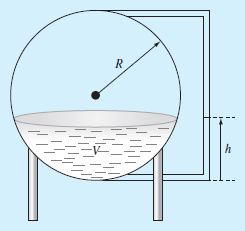

% El código no debe generar warnings
R = 3

R = 3

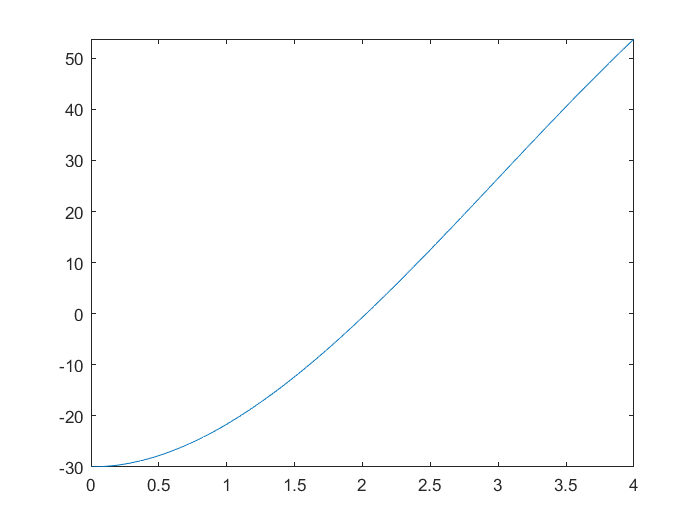

V_deseado = 30;
vol = @(h) pi*(h.^2).*((3*R - h)/3) - V_deseado;
fplot(vol,[0,4]) %podemos ver que el cruce con el eje x está en aproximadamente h = 2

[h,i] = secante(vol,0,4) %estabamos en lo correcto y lo hizo en 6 iteraciones

h = 2.0269

i = 6

3. [2 puntos] Determina todas las raíces de $f\left(x\right)=-14-20x+19x^2 -3x^3$. Grafica el polinomio para identificar en qué regiones se encuentran las raíces.

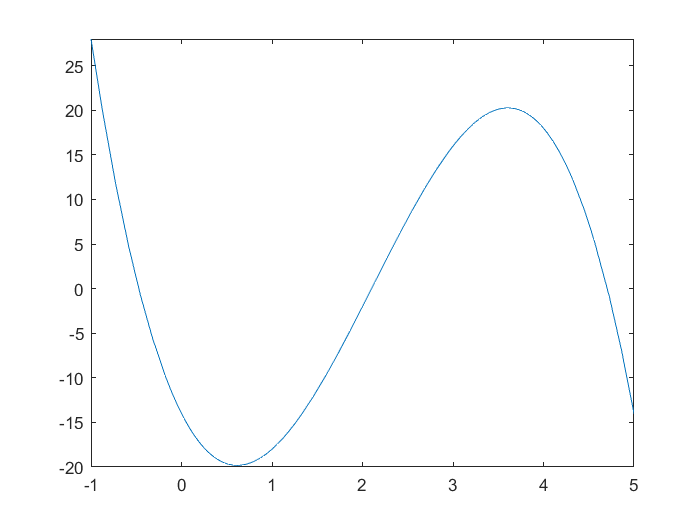

% El código no debe generar warnings
f = @(x) -14 -20*x + 19*x.^2 - 3*x.^3;
fplot(f,[-1,5]) %podemos ver que las raíces se encuentran cerca de 0, 2 y 4


pol = [-3,19,-20,-14]

pol =     -3    19   -20   -14


r = roots(pol) %

r =     4.7060
    2.0997
   -0.4723


## Optimización

4. [2 puntos] Encuentra el máximo de la función


$$f\left(x\right)=2\sin \left(x\right)-\frac{x^2 }{10}$$


en el intervalo [0,5].

Utiliza el método de Newton (escribe el código más abajo) o utiliza la función fminbnd de Matlab.

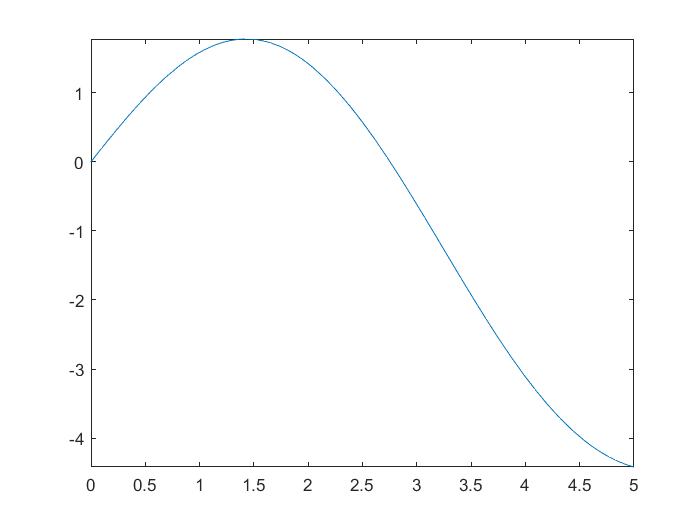

% El código no debe generar warnings
f = @(z) 2*sin(z) - (z.^2)/10;
fplot(f,[0,5]) %sé que el máximo debe de estar entre 1.3 y 1.5

[punto,i,min] = NewtonOptimizacion(f,1)

punto = 1.4276

i = 5

min = logical
   0


%Podemos notar que el resultado es correcto ya que el máximo lo encontró
%en 1.4 (como pudimos deducir de la gráfica) y que la bandera de mínimo nos
%dio 0, indicando que es un máximo.


5. [1 punto] Método de la secante.

function [x,i] = secante(f,a,b)
    rtol = eps;
    i = 0;
    xp = (a+b)/4;
    x = (a+b)/2;
    bandera = true;
    max_iters = 100;
    while bandera
        xa = xp;
        xp = x;
        sn = (f(xp)-f(xa))/(xp-xa);
        x  = xp - f(xp)/sn;
        i=i+1;
        bandera = abs(x-xp)>abs(x)*rtol && x~=0 && i<max_iters;
    end
end

6. [1 punto] Método de Newton para encontrar puntos críticos. 

Observa que la función debe regresar tres resultados. La variable min indíca si el punto crítico es un mínimo o un máximo.

function [x,i, min] = NewtonOptimizacion(f,x)
% Supone funciones doblemente diferenciables
% Encuentra un punto crítico de f
% min - indica si se trata de un mínimo (true) o máximo (false)
rtol = eps;
max_iters = 120;
fsym = sym(f); %convertimos f a una funcion simbolica para poder derivarla
dfs = diff(fsym);
ddfs  = diff(dfs);
ddf  = matlabFunction(ddfs);
df = matlabFunction(dfs);
i = 0;
bandera = true;
while bandera
    xp = x;
    x = xp-(df(xp)/ddf(xp));
    dfx = df(x);
    i = i+1;
    
    bandera = abs(x-xp)>abs(x)*rtol && dfx~=0 && i<max_iters;     
end

min = ddf(x)>0; %Si es un máximo regresará true


end